**Taller 2**

**Complex9**

clc;
clear all;
rng(0);
datos = importdata("complex9.txt");
X = datos(:,1:2);

% Diagrama de codo kmeans
fprintf("kmeans");

kmeans

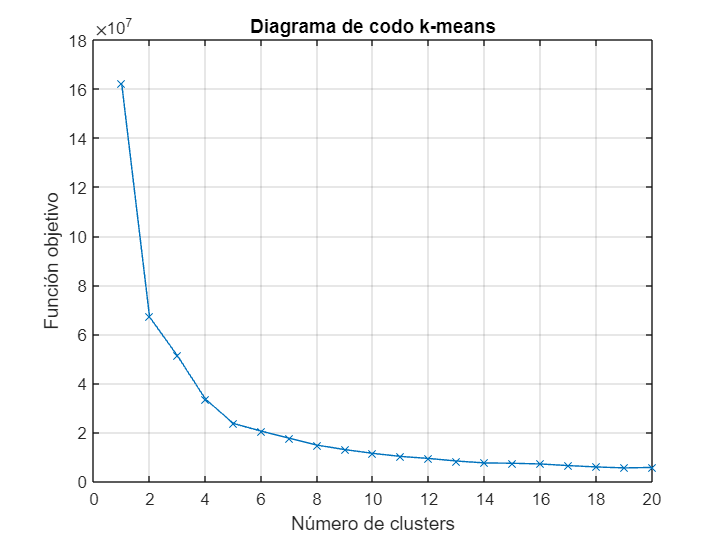

n = 20;
for i =1:n
    [idx, C, SumD] = kmeans(X,i);
    J(i) = sum(SumD);
    K(i) = i;
end

figure;
plot(K, J,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo");
title("Diagrama de codo k-means");

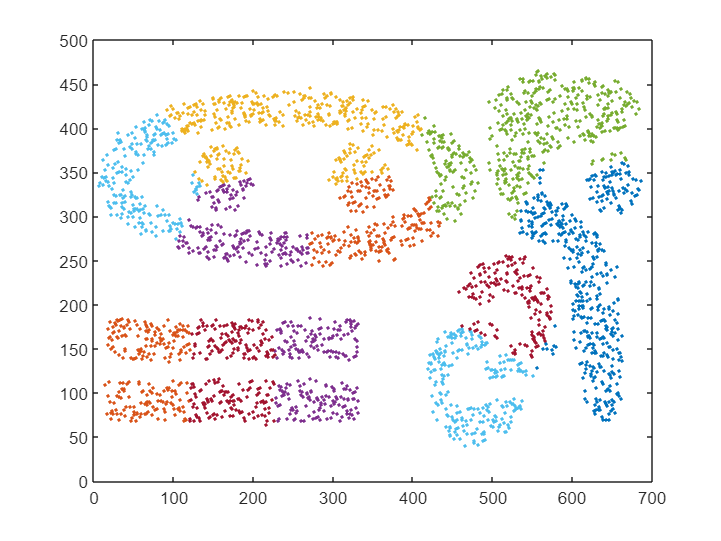


k=14;
idx = kmeans(X,k);

figure;
for i=1:k
plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)]);
hold on;
end


fprintf("kmeans");

kmeans

[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X,idx)

SSW = 46.3844

SSB = 212.8512

WB = 3.0509

SIL = 0.5887


fprintf("kmedoids");

kmedoids

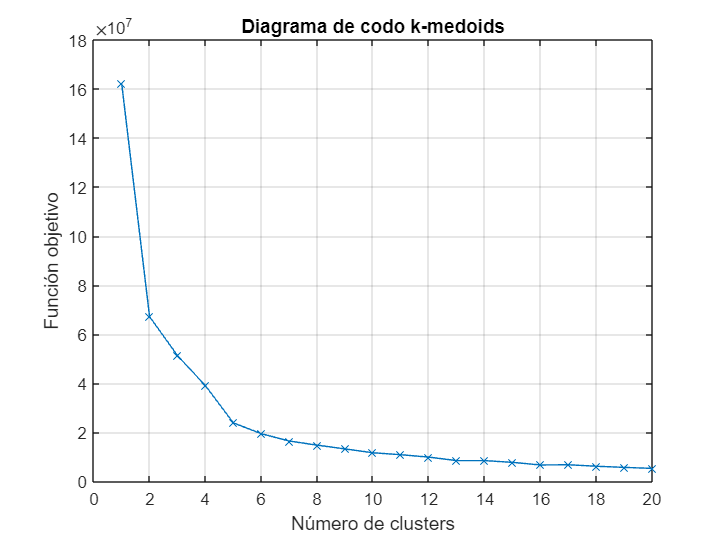


% Diagrama de codo kmedoids
for i =1:n
    [idx, C, SumD] = kmedoids(X,i);
    J(i) = sum(SumD);
    K(i) = i;
end

figure;
plot(K, J,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo");
title("Diagrama de codo k-medoids");

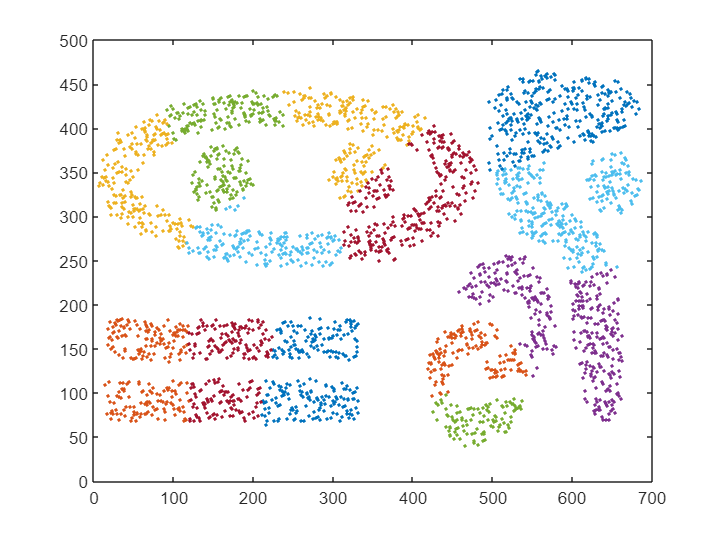


k=14;
idx = kmedoids(X,k);

figure;
for i=1:k
plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)]);
hold on;
end


[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X(:,1:2),idx)

SSW = 47.9522

SSB = 213.5675

WB = 3.1434

SIL = 0.5667


fprintf("DBSCAN");

DBSCAN


ep = clusterDBSCAN.estimateEpsilon(X,2,10)

ep = 9.8923

idx = dbscan(X,ep,10);

k1 = max(idx);
idx(idx==-1)= k1+1;
idx(idx==0)= k1+2;
k0 = min(idx)

k0 = 1

k1 = max(idx)

k1 = 83

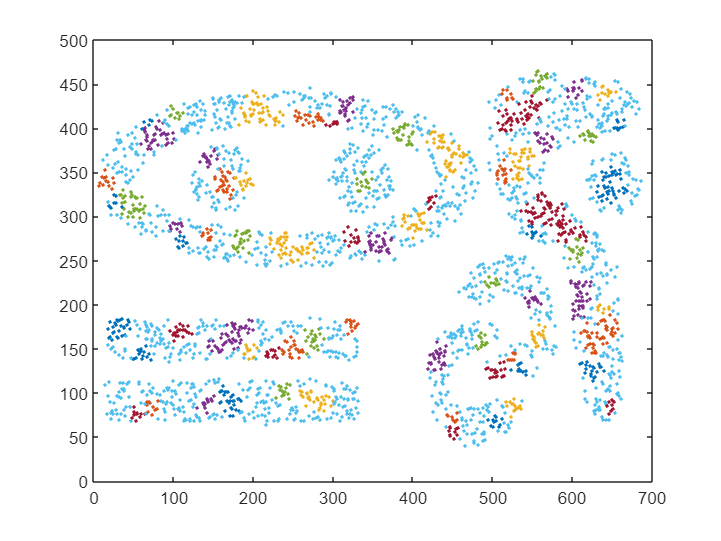


figure;
for i=k0:k1
plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)]);
hold on;
end


[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X(:,1:2),idx)

SSW = 104.8374

SSB = 123.4962

WB = 70.4597

SIL = -0.1181